% load FLP_analysis.mat from 1610_001
load('/Volumes/PcSSDA/20220214_1610_SW_001/FLP_analysis.mat');
tau_emp_1610_001=tau_empTrunc_all_darkonly;
tau_avg_1610_001=tau_avg_all_darkonly;
lifetime_histograms_all_dark_1610_001=lifetime_histograms_all(:,dark_acqs);

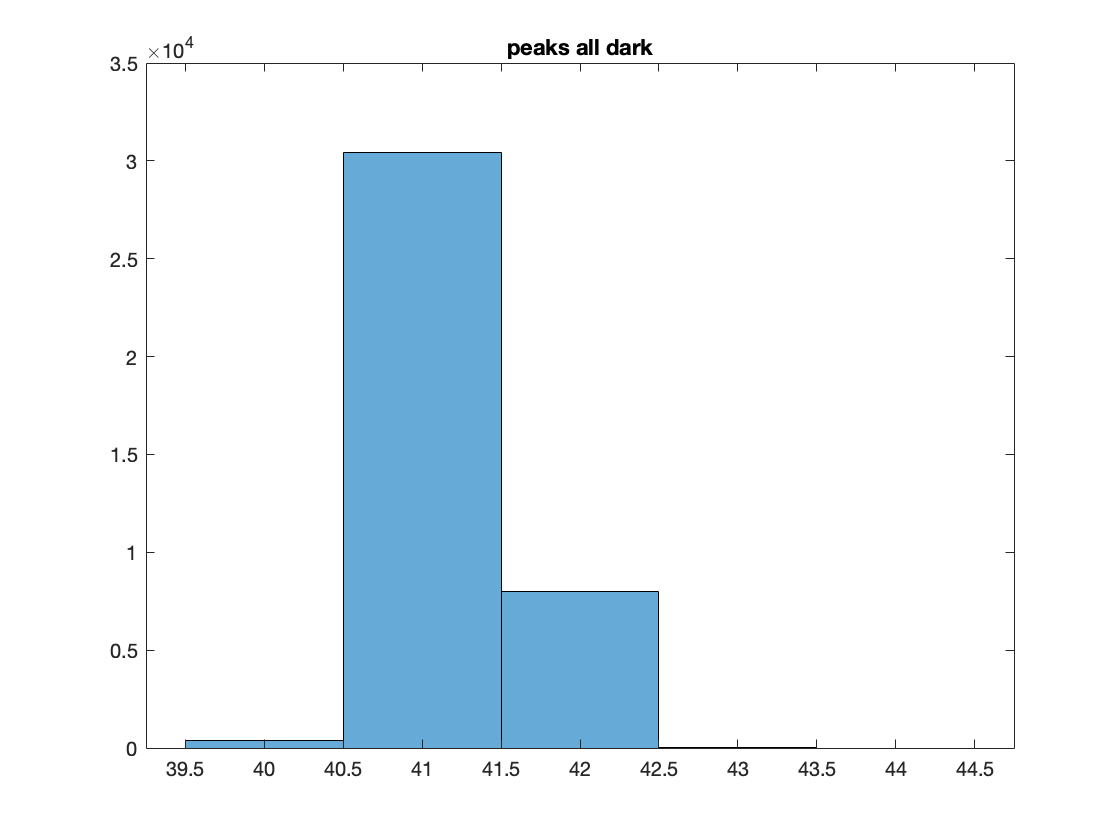

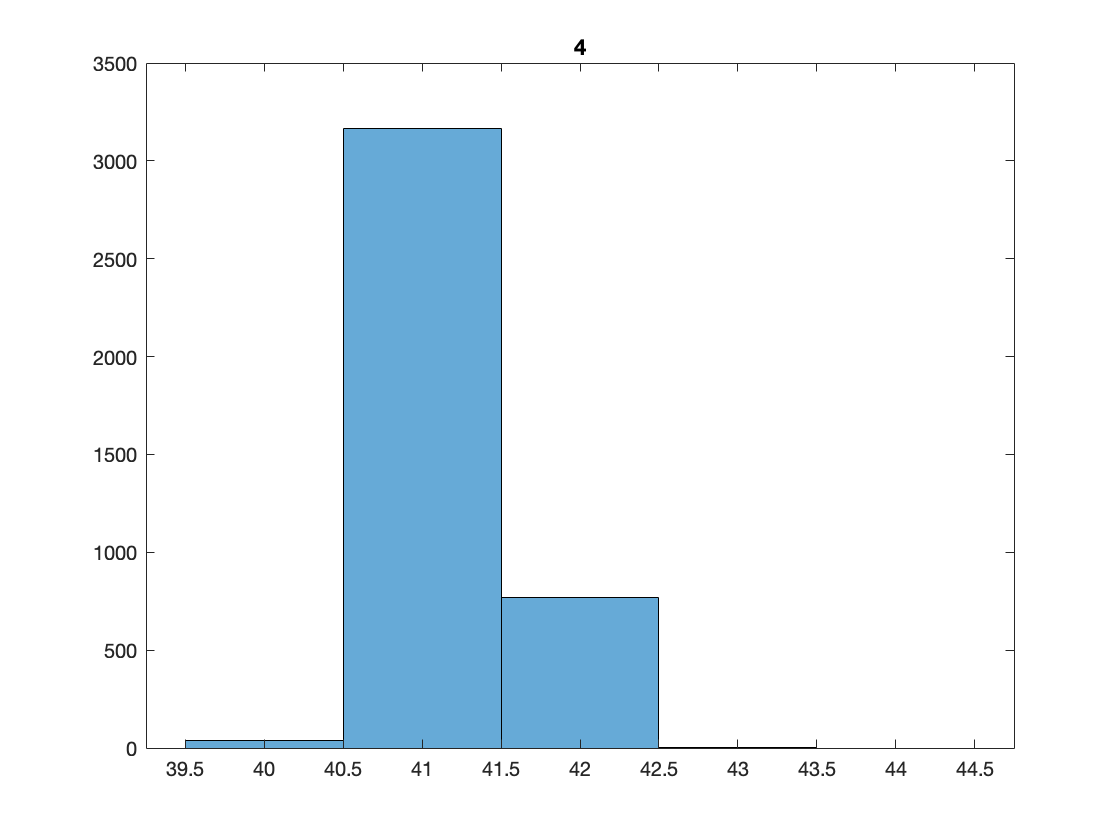

% load FLP_analysis.mat from 1610_002
load('/Volumes/PcSSDA/20220219_1610_SW_002/FLP_analysis.mat');

tau_emp_1610_002=tau_empTrunc_all_darkonly;
tau_avg_1610_002=tau_avg_all_darkonly;
lifetime_histograms_all_dark_1610_002=lifetime_histograms_all(:,dark_acqs);

% load FLP_analysis.mat from 1610_003
load('/Volumes/PcSSDA/20220314_1610_SW_003/FLP_analysis.mat');

tau_emp_1610_003=tau_empTrunc_all_darkonly;
tau_avg_1610_003=tau_avg_all_darkonly;
lifetime_histograms_all_dark_1610_003=lifetime_histograms_all(:,dark_acqs);

lifetime_histograms_all_dark_1610=[lifetime_histograms_all_dark_1610_001 lifetime_histograms_all_dark_1610_002 lifetime_histograms_all_dark_1610_003];

photon_counts_all=[];
peak_counts_all=[];

for i=1:size(lifetime_histograms_all_dark_1610,2)
    photon_count=sum(lifetime_histograms_all_dark_1610(:,i));
    photon_counts_all=[photon_counts_all photon_count];

    peak_count=max(lifetime_histograms_all_dark_1610(:,i));
    peak_counts_all=[peak_counts_all peak_count];
end
lifetime_histograms_all_dark_1610_norm1=lifetime_histograms_all_dark_1610./photon_counts_all;
lifetime_histograms_all_dark_1610_norm2=lifetime_histograms_all_dark_1610./peak_counts_all;

count1=size(tau_avg_1610_001,1)

count1 = 41909

count2=size(tau_avg_1610_001,1)+size(tau_avg_1610_002,1)

count2 = 80767


avg_hist1=mean(lifetime_histograms_all_dark_1610_norm2(:,1:count1)');
avg_hist2=mean(lifetime_histograms_all_dark_1610_norm2(:,count1+1:count2)');
avg_hist3=mean(lifetime_histograms_all_dark_1610_norm2(:,count2+1:end)');


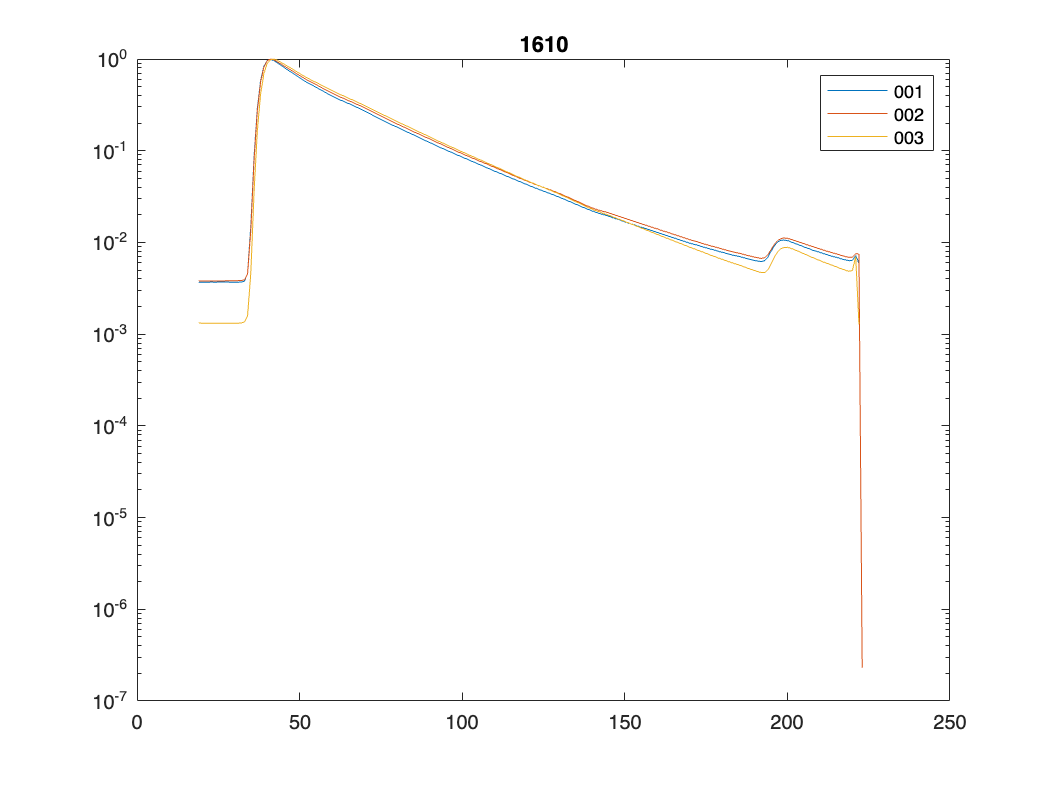

figure
semilogy(avg_hist1)
hold on
semilogy(avg_hist2)
hold on
semilogy(avg_hist3)
hold off
title('1610')
legend('001','002','003')